Recording a speech signal 

%Q3.a.1
my_record = audiorecorder(16000,8,1,-1); %(Fs,BitNum,Channel,Id)
disp("Record begin")    

Record begin


recordblocking(my_record,5);  % 4 seconds record

disp("Record end") 

Record end


play(my_record);

 Taking 2^16 samples

sampled_record=getaudiodata(my_record); % extract the audio data from the signal (vector)
filename = 'my_record.wav'; 
audiowrite(filename,sampled_record,16000); 
[sampled_record]=audioread('my_record.wav'); 
sampled_record= sampled_record.'; %   converting from a column vector to a row vector.
sampled_record=sampled_record(1:2^16); % save only 65536 samples 

Calculate the average power

%Q3.a.2
N=2^16; 
P=(1/N)*(sampled_record)*(sampled_record.');

Adding noise to samples

%Q3.b -
d2=0.205913858; 
d1=0.212552442; 
n=(0:1:N-1); 
w1=1.6+0.1*d1; 
w2=1.6+0.1*d2; 
w3=3; 
%------------------ BY DEFENITION---------------------
x_n=sampled_record; 
z_n=50*sqrt(P)*(cos(w1*n)+cos(w2*n)+cos(w3*n)); 
y_n=z_n+x_n; 
soundsc(y_n,16000);

Plotting the signals

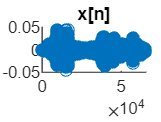

%Q3.c
n=(0:1:N-1); 
figure 
hold on 
title('x[n]'); 
stem(n,x_n);

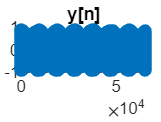


%Q3.c 
n=(0:1:N-1); 
figure 
hold on 
title('y[n]'); 
stem(n,y_n);

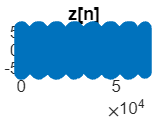


%Q3.c
figure 
hold on 
title('z[n]'); 
stem(n,z_n);

Ploting Y(exp(jw)): 

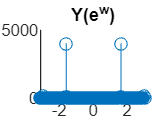

%Q3.d: Y_e_omega
k=(-63:64); 
omega=2*pi*k/128; 
Y_e_omega=fft(y_n); 
Y_e_omega=fftshift(Y_e_omega); 

figure; 
hold on 
title('Y(e^j^w)'); 
stem(omega,abs(Y_e_omega(1:512:N)));

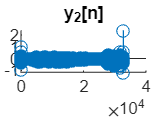


%Q3.f: 

y2_n=decimate(y_n,2); 
Y2_e_omega=fft(y2_n); 
Y2_e_omega=fftshift(Y2_e_omega); 
figure 
hold on 
title('y_2[n]'); 
stem(n(1:N/2),y2_n); 

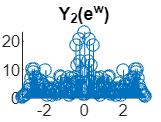


figure 
hold on 
title('Y_2(e^j^w)'); 
stem(omega,abs(Y2_e_omega(1:256:N/2))); 

soundsc(y2_n,8000);

